[predicted_labels,predicted_scores]=classify(netTransfer,augmented_imdsTest);

actual_labels=imdsTest.Labels;


figure;
cm= confusionchart(actual_labels,predicted_labels)

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


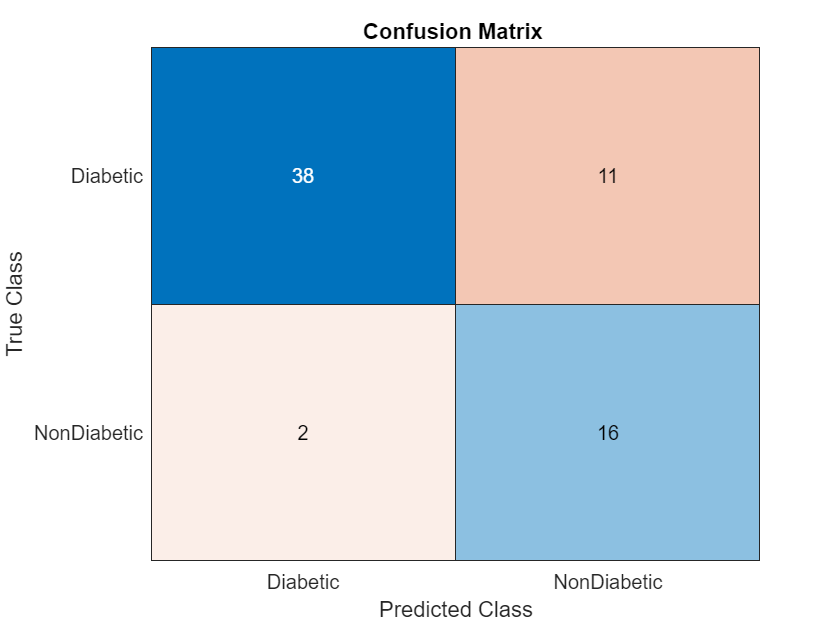

title('Confusion Matrix ')

tp=cm.NormalizedValues(1);
tn=cm.NormalizedValues(4);
fp=cm.NormalizedValues(2);
fn=cm.NormalizedValues(3);
accuracy = ((tp+tn)/(tp+fn+fp+tn))*100

accuracy = 80.5970

specificity = ((tn)/(tn+fp))*100

specificity = 88.8889

precision = ((tp)/(tp+fp))*100

precision = 95

sensitivity = ((tp)/(tp+fn))*100

sensitivity = 77.5510

F1score = ((2*precision*sensitivity)/(precision+sensitivity))

F1score = 85.3933